[(2 封私信) Wilson Loop计算Wannier Function Center演化并确定Z_2不变量(BHZ model & Kane Mele model)(Mathematica/Matlab) - 知乎](https://zhuanlan.zhihu.com/p/661862820)

# BHZ模型 WilsonLoop

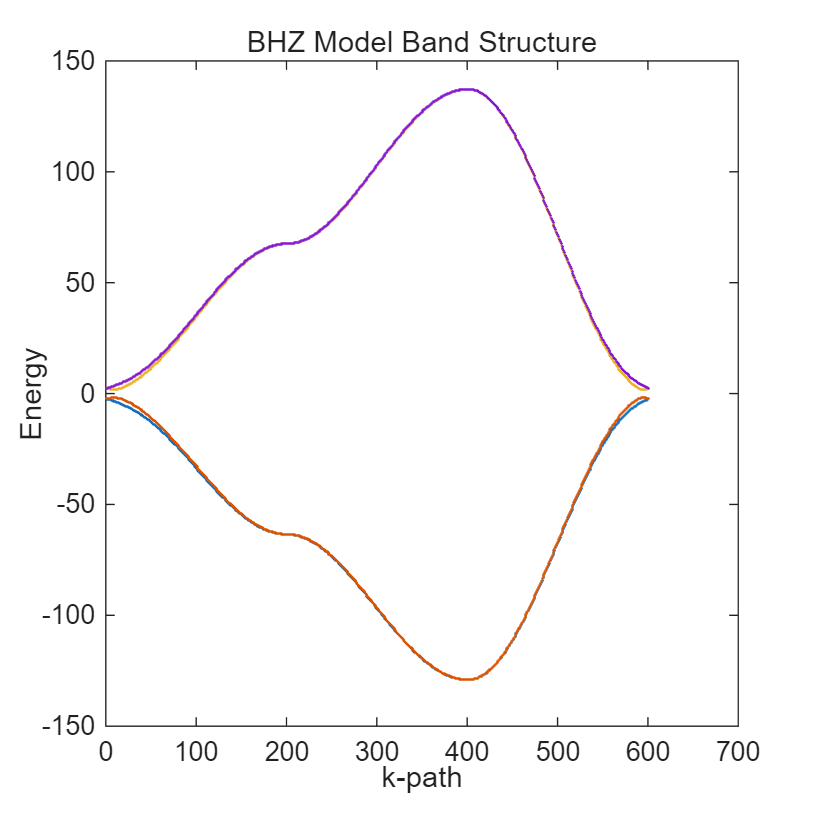


clear;
% 优化后的BHZ模型能带与Wilson环相位计算
% ----------- 能带计算向量化 -----------
n1 = 201;
l = linspace(0, 1, n1);

Gamma = [0, 0]; M = [pi, 0]; K = [pi, pi];

% 路径参数批量生成
l1 = l(1:end-1);
l2 = l(1:end-1);
l3 = l;

% 路径点批量生成
kpath1 = [M(1)*l1; M(2)*l1];
kpath2 = [(K(1)-M(1))*l2+M(1); (K(2)-M(2))*l2+M(2)];
kpath3 = [(Gamma(1)-K(1))*l3+K(1); (Gamma(2)-K(2))*l3+K(2)];

kx_all = [kpath1(1,:), kpath2(1,:), kpath3(1,:)];
ky_all = [kpath1(2,:), kpath2(2,:), kpath3(2,:)];

num_k = numel(kx_all);
band = zeros(4, num_k);

% 向量化能带计算
for idx = 1:num_k
    energy = eig(hamiltonianBHZ(kx_all(idx), ky_all(idx)));
    band(:, idx) = sort(energy);
end

% 绘制能带
figure; hold on;
colors = lines(4);
for i = 1:4
    scatter(1:num_k, band(i,:), 1, 'filled', 'MarkerFaceColor', colors(i,:));
end
xlabel('k-path'); ylabel('Energy'); title('BHZ Model Band Structure');
box on;

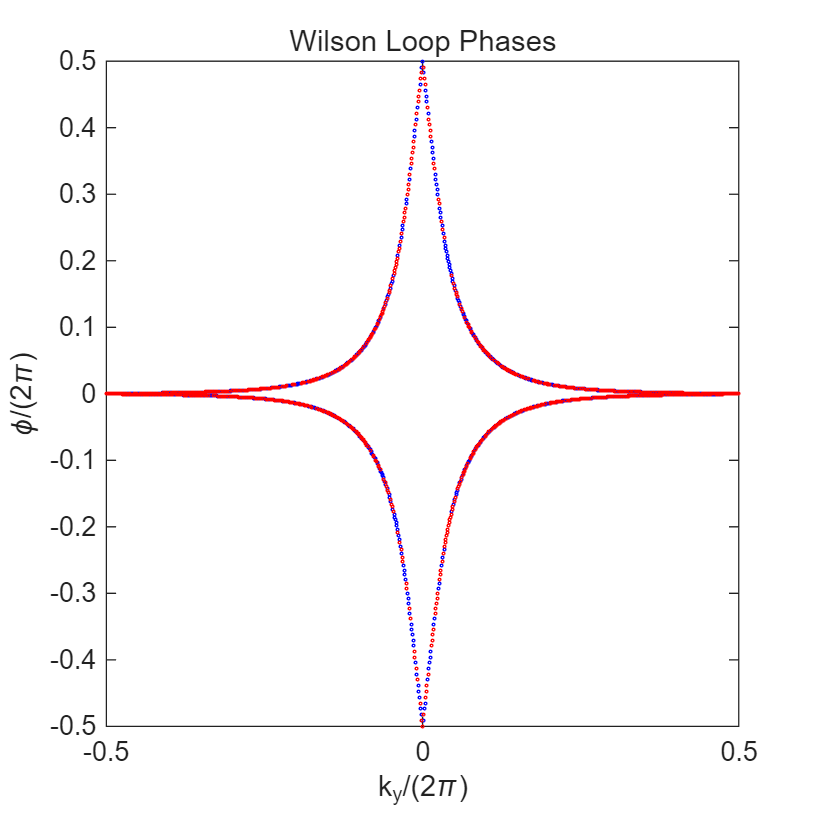


% ------------------BHZ哈密顿量定义------------------
function h = hamiltonianBHZ(kx, ky)
    a = 1;
    A = -13.68; B = -16.9; C = -0.0263; D = -0.514; M = -2.058; Delta = 1.2;
    s0 = eye(2); s1 = [0, 1; 1, 0]; s2 = [0, -1j; 1j, 0]; s3 = [1, 0; 0, -1];
    h1 = (C - 2*D/a^2*(2-cos(kx)-cos(ky)))*s0 + A/a*sin(kx)*s1 + A/a*sin(ky)*s2 ...
        - 2*B/a^2*(2-M/(2*B)-cos(kx)-cos(ky))*s3;
    h2 = (C - 2*D/a^2*(2-cos(kx)-cos(ky)))*s0 + A/a*sin(-kx)*s1 + A/a*sin(-ky)*(-s2) ...
        - 2*B/a^2*(2-M/(2*B)-cos(kx)-cos(ky))*s3;
    heff = blkdiag(h1, h2);
    hp = [0,0,0,-1j*Delta;0,0,1j*Delta,0;0,-1j*Delta,0,0;1j*Delta,0,0,0];
    h = hp + heff;
end

% ------------------Wilson环相位计算------------------
N = 2; Ny = 1001; Nx = 100; % N: 占据态数目, Nx, Ny: k空间采样点数
value = zeros(N, Ny); % 存储Wilson环本征值

for j = 1:Ny
    ky = 2 * pi * (j - 1) / (Ny - 1) - pi; % k_y取值
    Vector = zeros(N, Nx, 4); % 占据态矢量
    for i = 1:Nx
        kx = (i - 1) * 2 * pi / Nx - pi; % k_x取值
        [V, D] = eig(hamiltonianBHZ(kx, ky));
        [~, ind] = sort(diag(D));
        Vs = V(:, ind); % 按能量升序排列
        for j1 = 1:N
            Vector(j1, i, :) = Vs(:, j1);
        end
    end
    DM = eye(N); % Wilson环转移矩阵
    for i = 1:(Nx - 1)
        F = zeros(N);
        for m = 1:N
            for n = 1:N
                F(m, n) = dot(squeeze(Vector(m, i, :)), squeeze(Vector(n, i + 1, :)));
            end
        end
        DM = DM * F;
    end
    % 闭合环
    F1 = zeros(N);
    for m = 1:N
        for n = 1:N
            F1(m, n) = dot(squeeze(Vector(m, Nx, :)), squeeze(Vector(n, 1, :)));
        end
    end
    DM = DM * F1;
    value(:, j) = eig(DM); % 记录本征值
end

% 绘制Wilson环相位
anglev = angle(value) / (2 * pi);
Ky = ((1:Ny) - 1) / (Ny - 1) - 0.5;
figure;
hold on;
scatter(Ky, anglev(1, :), 1, "blue");
scatter(Ky, anglev(2, :), 1, "red");
xlabel("k_y/(2\pi)");
ylabel("\phi/(2\pi)");
axis([-0.5 0.5 -0.5 0.5]);
title('Wilson Loop Phases');
box on;
hold off

# Kane-Mele模型 Wilsonloop

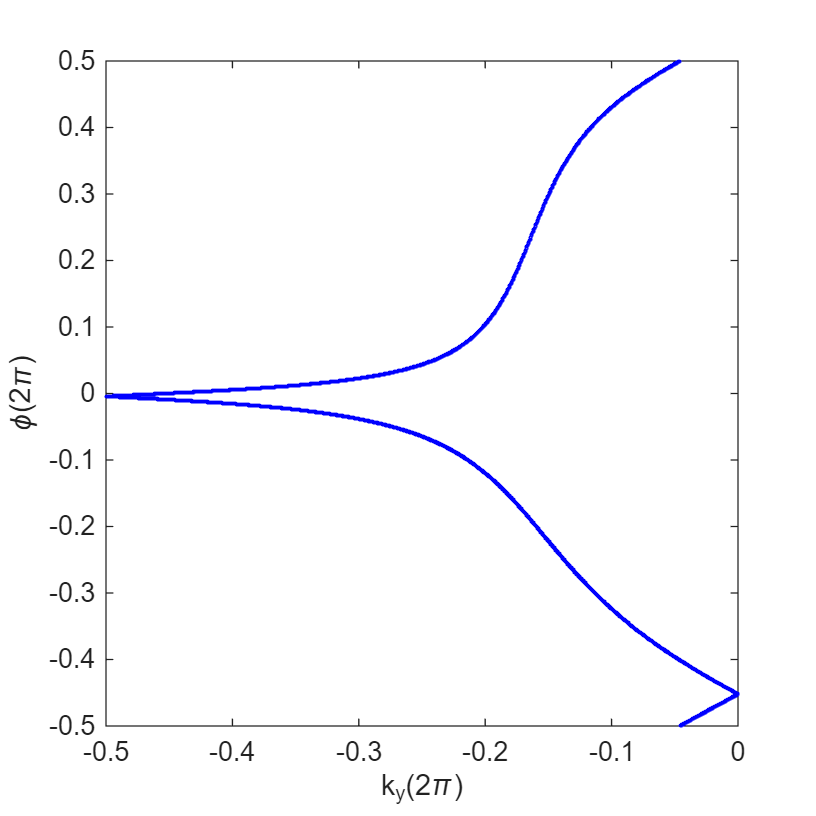

function h = hamiltonianKaneMele(kx,ky)
%hamiltonianKaneMele hamiltonian of Kane Mele model
% t=1;lv=0.4;lSO=0.06;lR=0.05; % topological trivial
t=1;lv=0.1;lSO=0.06;lR=0.05; % topological nontrivial
% t=1;lv=0.4;lSO=0.06;lR=0.05;
s0=[1,0;0,1];s1=[0,1;1,0];s2=[0,-1j;1j,0];s3=[1,0;0,-1];
d1=t*(1+2*cos(kx/2)*cos(sqrt(3)*ky/2));
d2=lv;
d3=lR*(1-cos(kx/2)*cos(sqrt(3)*ky/2));
d4=-sqrt(3)*lR*sin(kx/2)*sin(sqrt(3)*ky/2);
d12=-2*t*cos(kx/2)*sin(sqrt(3)*ky/2);
d15=lSO*(2*sin(kx)-4*sin(kx/2)*cos(sqrt(3)*ky/2));
d23=-lR*cos(kx/2)*sin(sqrt(3)*ky/2);
d24=sqrt(3)*lR*sin(kx/2)*cos(sqrt(3)*ky/2);
g1=kron(s1,s0);
g2=kron(s3,s0);
g3=kron(s2,s1);
g4=kron(s2,s2);
g12=-kron(s2,s0);
g15=kron(s3,s3);
g23=-kron(s1,s1);
g24=-kron(s1,s2);
h=d1*g1+d2*g2+d3*g3+d4*g4+d12*g12+d15*g15+d23*g23+d24*g24;
end


N=2;Ny=1001;Nx=100;
value=zeros(N,Ny);
b1=[2,2*sqrt(3)/3]*pi;b2=[2,-2*sqrt(3)/3]*pi;
for j=1:Ny
    Vector=zeros(N,Nx,4);
    for i=1:Nx
        k=((i-1)/Nx)*b1+(j-1)/(Ny-1)*b2/2;
        kx=k(1);ky=k(2);
        [V,D]=eig(hamiltonianKaneMele(kx,ky));
        [d,ind]=sort(diag(D));
        Vs=V(:,ind);
        for j1=1:N
            Vector(j1,i,:)=Vs(:,j1);
        end
    end
    DM=eye(2);
    for i=1:(Nx-1)
        F=eye(2);
        for m=1:N
            for n=1:N
                F(m,n)=dot(Vector(m,i,:),Vector(n,i+1,:));
            end
        end
        DM=DM*F;
    end
    F1=eye(2);
    for m=1:N
        for n=1:N
            F1(m,n)=dot(Vector(m,Nx,:),Vector(n,1,:));
        end
    end
    DM=DM*F1;
    value(:,j)=eig(DM);
end
anglev=angle(value)/(2*pi);
Ky=(((1:Ny)-1)/(Ny-1)-1)/2;
scatter(Ky,anglev(1,:),1,'blue')
axis([-0.5 0 -0.5 0.5])
hold on
scatter(Ky,anglev(2,:),1,'blue')
xlabel("k_y(2\pi)")
ylabel("\phi(2\pi)")
box on
% 沿着  路径绘制能带的代码如下

n1=201;
l=linspace(0,1,n1);
Gamma=[0,0];M=[1,sqrt(3)/3]*pi;K=[4*pi/3,0];
band=zeros(4,3*n1-2);
for i=1:(n1-1)
    kx=M(1)*l(i);ky=M(2)*l(i);
    energy=eig(hamiltonianKaneMele(kx,ky));
    energy_s=sort(energy);
    band(:,i)=energy_s;
end
for i=1:(n1-1)
    kx=(K(1)-M(1))*l(i)+M(1);ky=(K(2)-M(2))*l(i)+M(2);
    energy=eig(hamiltonianKaneMele(kx,ky));
    energy_s=sort(energy);
    band(:,i+n1-1)=energy_s;
end
for i=1:n1
    kx=(Gamma(1)-K(1))*l(i)+K(1);ky=(Gamma(2)-K(2))*l(i)+K(2);
    energy=eig(hamiltonianKaneMele(kx,ky));
    energy_s=sort(energy);
    band(:,i+2*n1-2)=energy_s;
end
scatter(1:(3*n1-2),band(1,:),1,'filled')
hold on
scatter(1:(3*n1-2),band(2,:),1,'filled')
scatter(1:(3*n1-2),band(3,:),1,'filled')
scatter(1:(3*n1-2),band(4,:),1,'filled')


N=2;Ny=1001;Nx=100;
value=zeros(N,Ny);
b1=[2,2*sqrt(3)/3]*pi;b2=[2,-2*sqrt(3)/3]*pi;
for j=1:Ny
    Vector=zeros(N,Nx,4);
    for i=1:Nx
        k=((i-1)/Nx)*b1+(j-1)/(Ny-1)*b2/2;
        kx=k(1);ky=k(2);
        [V,D]=eig(hamiltonianKaneMele(kx,ky));
        [d,ind]=sort(diag(D));
        Vs=V(:,ind);
        for j1=1:N
            Vector(j1,i,:)=Vs(:,j1);
        end
    end
    DM=eye(2);
    for i=1:(Nx-1)
        F=eye(2);
        for m=1:N
            for n=1:N
                F(m,n)=dot(Vector(m,i,:),Vector(n,i+1,:));
            end
        end
        DM=DM*F;
    end
    F1=eye(2);
    for m=1:N
        for n=1:N
            F1(m,n)=dot(Vector(m,Nx,:),Vector(n,1,:));
        end
    end
    DM=DM*F1;
    value(:,j)=eig(DM);
end
anglev=angle(value)/(2*pi);
Ky=(((1:Ny)-1)/(Ny-1)-1)/2;
scatter(Ky,anglev(1,:),1,'blue')
axis([-0.5 0 -0.5 0.5])
hold on
scatter(Ky,anglev(2,:),1,'blue')
xlabel("k_y(2\pi)")
ylabel("\phi(2\pi)")
box on

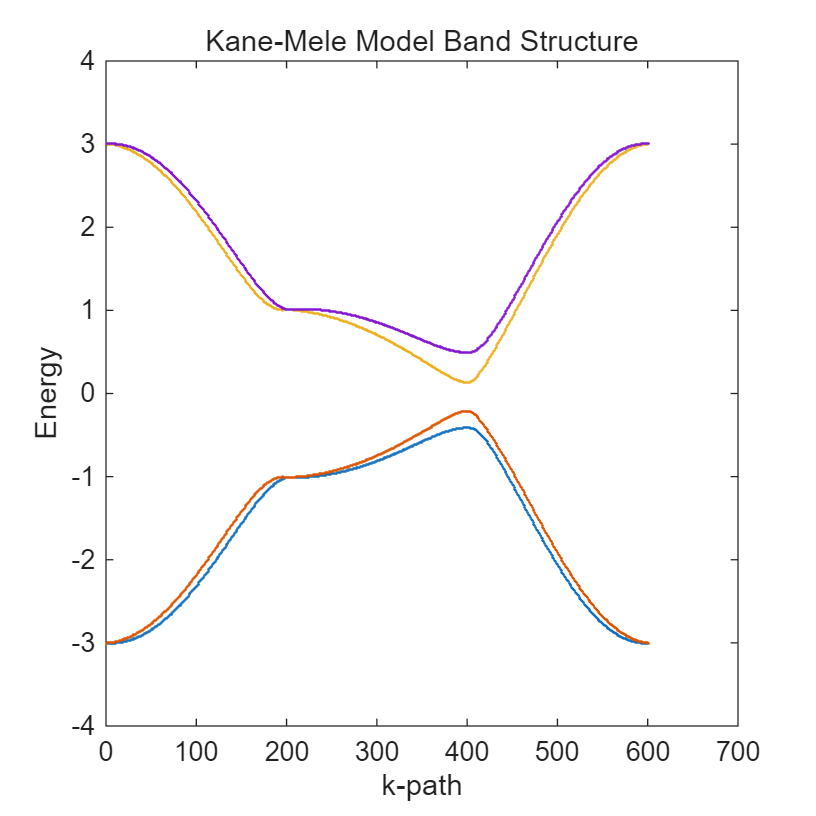

% ----------- 能带绘制向量化 -----------
n1 = 201;
l = linspace(0, 1, n1);

Gamma = [0, 0];
M = [1, sqrt(3)/3] * pi;
K = [4*pi/3, 0];

% 路径参数批量生成
l1 = l(1:end-1);
l2 = l(1:end-1);
l3 = l;

% 路径点批量生成
kpath1 = [M(1)*l1; M(2)*l1];
kpath2 = [(K(1)-M(1))*l2+M(1); (K(2)-M(2))*l2+M(2)];
kpath3 = [(Gamma(1)-K(1))*l3+K(1); (Gamma(2)-K(2))*l3+K(2)];

kx_all = [kpath1(1,:), kpath2(1,:), kpath3(1,:)];
ky_all = [kpath1(2,:), kpath2(2,:), kpath3(2,:)];

num_k = numel(kx_all);
band = zeros(4, num_k);

% 向量化能带计算
for idx = 1:num_k
    energy = eig(hamiltonianKaneMele(kx_all(idx), ky_all(idx)));
    band(:, idx) = sort(energy);
end

figure; hold on;
colors = lines(4);
for i = 1:4
    scatter(1:num_k, band(i,:), 1, 'filled', 'MarkerFaceColor', colors(i,:));
end
xlabel('k-path');
ylabel('Energy');
title('Kane-Mele Model Band Structure');
box on;